% Create the closed system transfer function.
s=tf('s');
Gopen=30*(s+1)/(s*(s+5)*(s^2+4*s+6))


Gopen =
 
           30 s + 30
  ---------------------------
  s^4 + 9 s^3 + 26 s^2 + 30 s
 
Continuous-time transfer function.



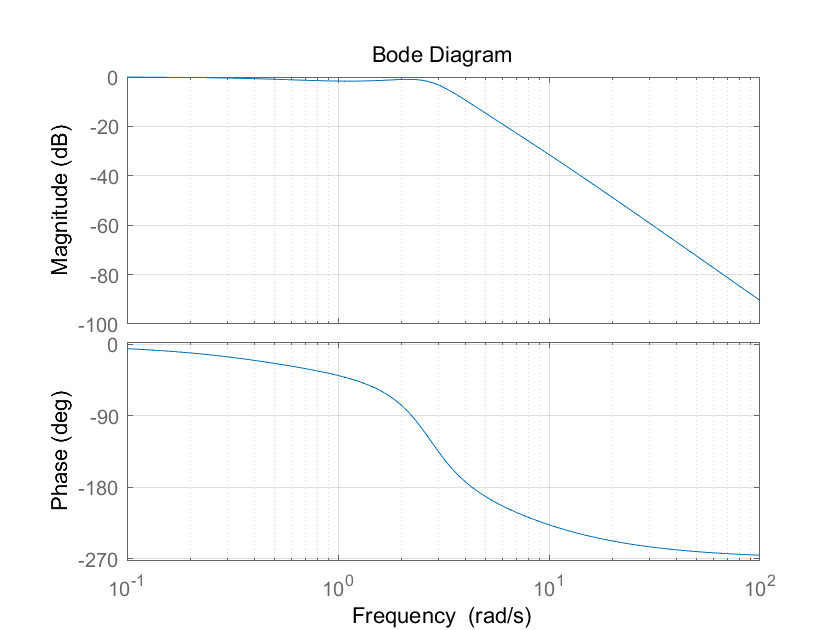

Gclosed=Gopen/(1+Gopen);

% Draw the bode chart of the system
w=logspace(-1,2,100);
bode(Gclosed,w);
grid on;


% Calculate the bandwith of the closed system.
wb=bandwidth(Gclosed);
j=sqrt(-1);
abs(polyval(Gclosed.Numerator{1},j*wb)/polyval(Gclosed.Denominator{1},j*wb))

ans = 0.7079

fprintf('The bandwidth of the system is %f rad/s.\n',wb)

The bandwidth of the system is 2.948719 rad/s.



% Calculate the peak gain and peak frequency.
% Mr --- The peak gain of the closed system
% Wr --- The peak frequency of the closed system
[Mr,Wr]=getPeakGain(Gclosed);
fprintf("The peak gain of the closed system is %f.\n",Mr);

The peak gain of the closed system is 1.000000.


fprintf("The peak frequency of the closed system is %f rad/s.\n",Wr);

The peak frequency of the closed system is 0.000000 rad/s.


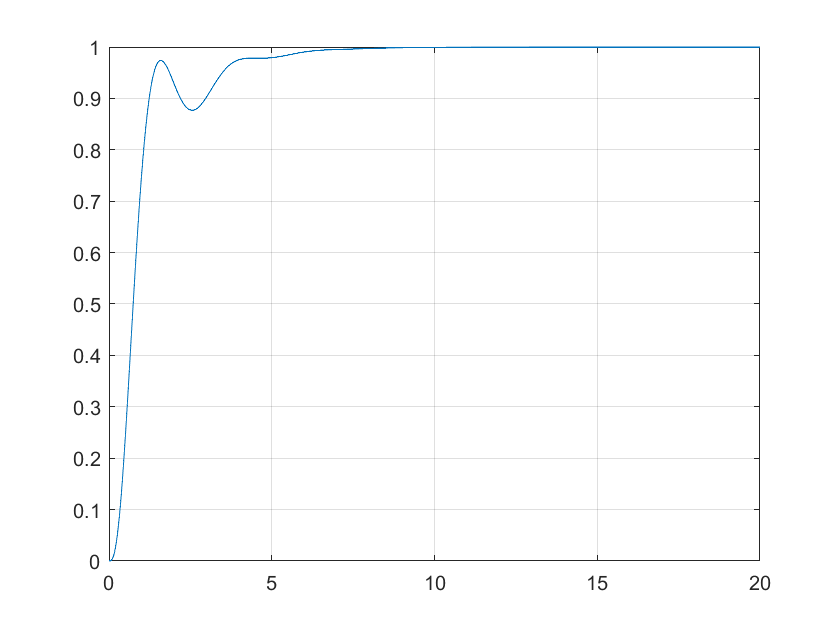


% Calculate the step response.
t=[0:0.000001:20];
y=step(Gclosed,t);
% Plot the step response.
figure;
plot(t,y);
grid on;

[OSValue,OSIndex]=max(y);
ys=y(length(t));
% Get the peak parameters.
Mp=(OSValue-ys)/ys*100;
tp=t(OSIndex);
fprintf('The unit step response overshoot is %f%%.',Mp);

The unit step response overshoot is 0.000000%.

fprintf('The unit step response peak time is %fs\n.',tp);

The unit step response peak time is 20.000000s
.

% Get the raise time of the step response.
tr=t(find(y>=ys,1,'first')); % From the index 1.
fprintf('The unit step response raise time is %fs\n.',tr);

The unit step response raise time is 20.000000s
.

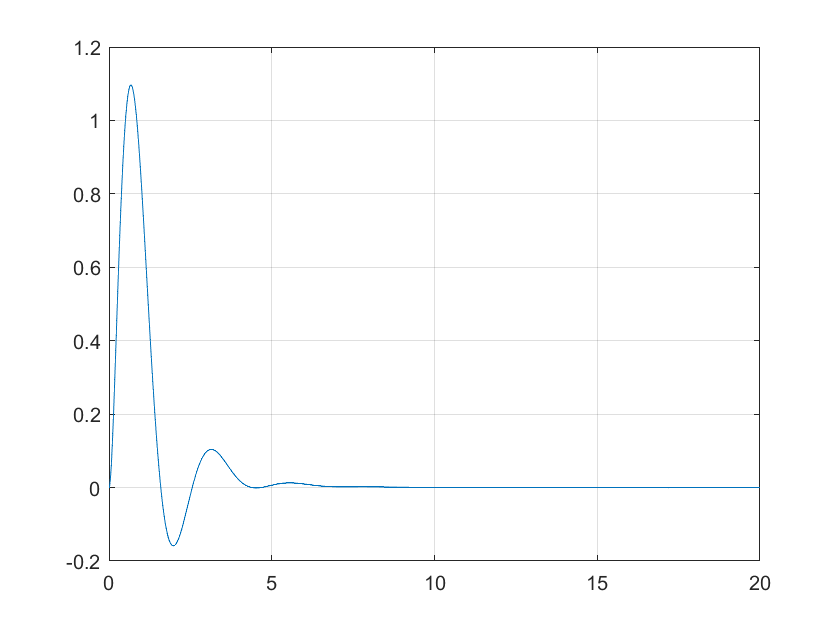


% Give the impulse response.
yi=impulse(Gclosed,t);
% Plot the step response.
figure;
plot(t,yi);
grid on;